name='六号房';
volume='3200立方米';
temperature = '28';
plant = 'cabbage ';
green_house_6 = struct('name',name,'volume',volume,'temperature',temperature,'plant',plant);
green_house_6

green_house_6 = 包含以下字段的 struct :
           name: '六号房'
         volume: '3200立方米'
    temperature: '28'
          plant: 'cabbage '


volume='3200立方米';
temperature = '28';
plant = 'cabbage ';
for i = 1:6
           name = [num2str(i)  '号房'];
	green_house(i)=struct('name',name,'volume',volume,'temperature',temperature,'plant',plant);
end
green_house

green_house = 包含以下字段的 1×6 struct 数组:
    name
    volume
    temperature
    plant


green_house(2)

ans = 包含以下字段的 struct :
           name: '2号房'
         volume: '3200立方米'
    temperature: '28'
          plant: 'cabbage '


patient1.name = 'John Doe';
patient1.billing = 127;
patient1.test = [79 75 73; 180 178 177.5; 220 210 205];
patient1

patient1 = 包含以下字段的 struct :
       name: 'John Doe'
    billing: 127
       test: [3×3 double]


n={'John Doe' 'Ann Lane' 'Alan Johnson'}; %细胞数组
b=[127 28.5 95.8];
t1=[79 75 73; 180 178 177.5; 220 210 205];
t2=[68 70 68; 118 118 119; 172 170 169];
t3=[37 38 36; 119 121 120; 165 166 159];
t(:,:,1) = t1; t(:,:,2)=t2; t(:,:,3) = t3;
for i = 1:3
 	patient2(i).name = n{i};  patient2(i).billing = b(i);
 	patient2(i).test = t(:,:,i);
end
patient2

A=struct('data',[3 4 7;8 0 1],'nest', ...
struct('testnum','Test 1','xdata',[4 2 8],'ydata',[7 1 6]));
A(2).data=[9 3 2;7 6 5];
A(2).nest.testnum='Test 2';
A(2).nest.xdata=[3 4 2];
A(2).nest.ydata=[5 0 9];
A

A = 包含以下字段的 1×2 struct 数组:
    data
    nest


A(1).data

ans =      3     4     7
     8     0     1


A(2).nest

ans = 包含以下字段的 struct :
    testnum: 'Test 2'
      xdata: [3 4 2]
      ydata: [5 0 9]


a={20,'matlab',ones(2,3)}

a = 1×3 cell 数组
    {[20]}    {'matlab'}    {2×3 double}


green_house_6={'六号房','3200立方米',28,'cabbage'}

green_house_6 = 1×4 cell 数组
    {'六号房'}    {'3200立方米'}    {[28]}    {'cabbage'}


练习一： excel数据读取和写入

试着读取量表数据class_test，并将被试的ID顺序输出；分别计算左右前测和后测的差值，输出到文件备用。

data = xlsread('课堂练习/class_test.xlsx', 'A2:E31');
idx = data(:,1);
diff_left = data(:,2) - data(:,3)

diff_left =    -0.4000
         0
   -1.6000
    2.7400
   -0.6000
    0.0600
   -0.5400
   -0.5300
   -1.2000
    0.5300


diff_right = data(:,4) - data(:,5)

diff_right =     0.4000
    1.3300
   -1.2000
    2.7400
    1.6000
    3.8000
    0.7300
   -0.6000
    2.3500
    0.2700


diff = cat(2, idx, diff_left, diff_right)

diff =     1.0000   -0.4000    0.4000
    2.0000         0    1.3300
    3.0000   -1.6000   -1.2000
    4.0000    2.7400    2.7400
    5.0000   -0.6000    1.6000
    6.0000    0.0600    3.8000
    7.0000   -0.5400    0.7300
    8.0000   -0.5300   -0.6000
    9.0000   -1.2000    2.3500
   10.0000    0.5300    0.2700


[status, message] = xlswrite('课堂练习/output.xlsx', diff);

练习二:  多文件读取

假设我们分别有一组病人一组正常人的功能脑图像数据，我们使用了脑模板（264个脑区）构建了一个脑网络，那我们现在要读取全部的文件(PA_ROI and HC_ROI)，然后计算正常人组和病人组的平均脑网络相关系数值（264x264)，并作图。

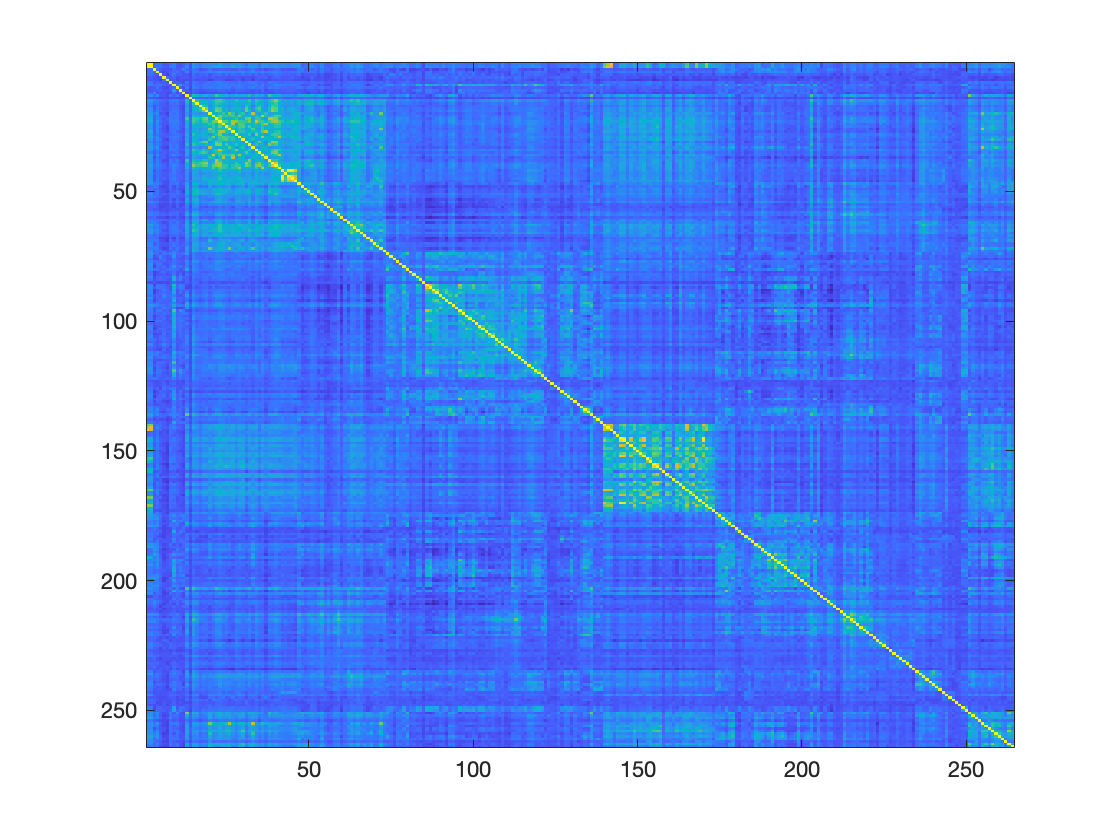

HC_files = dir('课堂练习/HC_ROI/*.mat');
PA_files = dir('课堂练习/PA_ROI/*.mat');

hc = zeros(264,264);
pa = zeros(264,264);

for i=1:length(HC_files)
    hcx = load([HC_files(i).folder '/' HC_files(i).name]);
    hc = hc + hcx.ROICorrelation_FisherZ;
    pax = load([PA_files(i).folder '/' PA_files(i).name]);
    pa = pa + pax.ROICorrelation_FisherZ;
end

hc = hc/length(HC_files);
pa = pa/length(PA_files);

imagesc(hc)

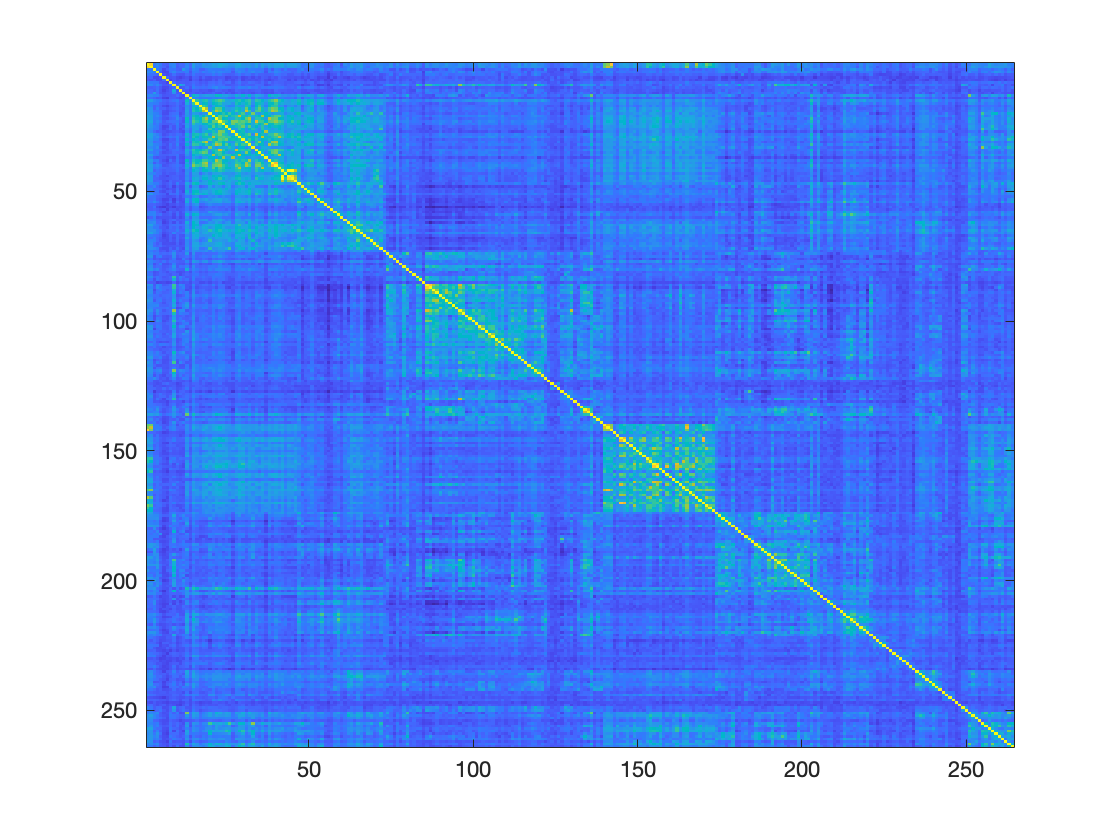

imagesc(pa)